[X, Y] = meshgrid(1:256);

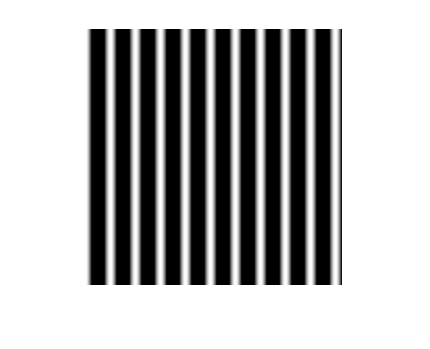

% Construct 2D sine wave
freq = 2*pi*0.04;
ang = pi * 0;
phase = pi * 0;
sinf = cos(freq*(cos(ang)*X+sin(ang)*Y) + phase);
imshow(sinf)

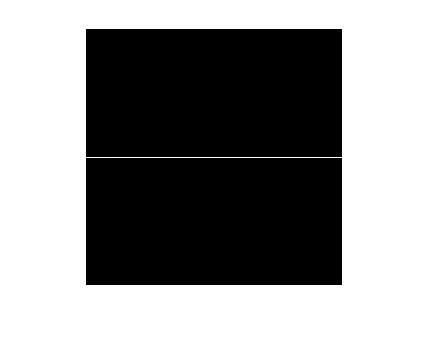

ans = 2.1633e-07


F = dft2(sinf);
F = fftshift(F);
figure;imshow(log(abs(F)),[-1 5])

% Construct rect
rect_ang = 0;
rect_width = 1;
rect_r = 4;
rect_center = [0, 0];
rect = zeros(256, 256);
rect(128-rect_width*rect_r/2:128+rect_width*rect_r/2, 128-rect_width/2:128+rect_width/2)=1;

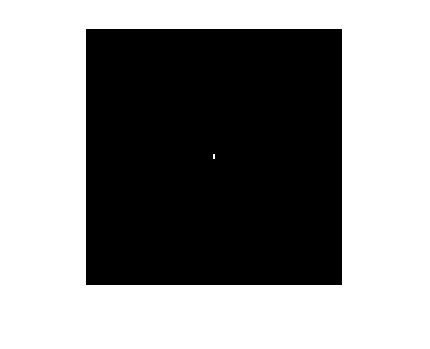

rect=rect(1:256, 1:256);
rect = imrotate(rect, rect_ang, 'bicubic', 'crop');
rect = imtranslate(rect,rect_center);
figure;imshow(rect)

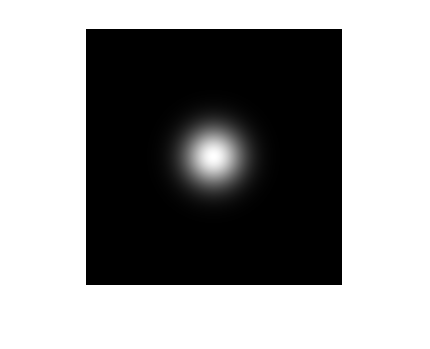

ans = 3

% Construct Gauss
gauss_std = 20;
gauss = exp(-((X-128).^2+(Y-128).^2)/(2*gauss_std^2));
figure;imshow(gauss)